%%this is the preliminary function to create our spectral 
%analizer. We will be using MATLAB's built in code for fft and
%so forth to do the implementation of this.


%sets the basic parameters of frame size and sample rate of the system
SampleRate = 48000;
FrameSize = 2048;
NumChannels = 1;


%sets the fundamental frequency
fundamentalFrequency = SampleRate/FrameSize;


%sets the limits of the plot
x_lower = 0;
x_upper = 10000;
y_lower = -10;
y_upper = 50;


%sets alpha, the coefficient we use to calculate the averaged power
alpha = 0.50;

%creates the coefficients for the square wave fourier series
fourier_coefficients_length = 10;

fourier_coefficients = zeros([fourier_coefficients_length 1]);
fourier_coefficients(1) = 1/2;
for i = 2:fourier_coefficients_length
    if mod(i,2)
        fourier_coefficients(i) = 2/(pi*i);
    end
end

fourier_coefficients_dB = 20.*log10(fourier_coefficients);

%sets up the audioReader object
audioReader = audioDeviceReader('NumChannels',NumChannels, ...
    'BitDepth','24-bit integer', ...
    'SamplesPerFrame',FrameSize, ...
    'SampleRate',SampleRate);

%sets up the audio writer
audioWriter = audioDeviceWriter('SampleRate',SampleRate, ...
    'BufferSize', FrameSize, ...
    'BitDepth', '24-bit integer');

%this starts the recording of the data
disp('Starting Processing');

Starting Processing


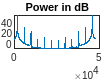


%creates array to store the current averaged power
currentAveragePower = zeros([FrameSize 1]);

%creates array to store the previous averaged power
previousAveragePower = zeros([FrameSize 1]);


%creates the counter to help us create the average power
counter = 1;

while 1
    
    %gets the audio data of one frame
    inputData = step(audioReader);
    
    %gets the FFT of the input data for the one frame, of length 1024
    inputDataFFT = fft(inputData);

    %gets the instantaneous power of the inputDataFFT
    inputDataFFTPower = real(inputDataFFT).*real(inputDataFFT) + imag(inputDataFFT).*imag(inputDataFFT);
    


    %finds the current averaged power array
    currentAveragePower = (1-alpha).*inputDataFFTPower + alpha.*previousAveragePower;
    
    %sets the previous averaged power array to the current power array
    previousAveragePower = currentAveragePower;   

    %creates the space to go from zero hertz up to the sample rate
    x = linspace(0, SampleRate, FrameSize);

    %does the same plot, but now in dB
    plot(x,10*log10(currentAveragePower));
    hold on;
    title("Power in dB");
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    %limits x to half the samplingfrequency for nyquist
    xlim([x_lower x_upper]);
    ylim([y_lower y_upper]);
    drawnow limitrate
    hold off;

    
    %outputs the just processed audio data to the writer
    step(audioWriter, inputData);
    



end